## Analysis of Solid/Liquid data with two methods of background.

First get the problemDefs etc by using an existing RasCAL1 project as usual (use original_DSPC_bilayer from the Rascal demo's folder).

addRatPaths()

debug


[problem,controls] = r1ToProblemDef('original_dspc_bilayer.mat')

problem =   problemDef with properties:

         experimentType: 'standard'
     experimentGeometry: 'substrate/liquid'
                nParams: 22
                 params: [5.0406 18.6723 3.4002e-06 21.0069 -3.4923e-07 5.9060 8.0722 19.8373 4.9879e-10 9.8423 1.0059e-06 6.6955 28.0113 10.0000 1.0000e-06 3.5028 17.1338 -1.6289e-07 16.4869 29.5219 99.9965 23.4506]
             paramNames: {1×22 cell}
            paramConstr: {1×22 cell}
          paramFitYesNo: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
           nBackgrounds: 2
            backgrounds: [2.0841e-06 3.1708e-06]
        backgroundNames: {'Background D2O'  'Background 2'}
       backgroundConstr: {[5.0000e-10 7.0000e-06]  [1.0000e-10 5.0000e-06]}
     backgroundFitYesNo: [1 1]
          nScalefactors: 2
           scalefactors: [0.1029 0.1432]
       scalefactorNames: {'Scalefactor 1'  'Scalefactor 2'}
      scalefactorConstr: {[0.0500 0.2000]  [0.0500 

controls =   controlsDef with properties:

            parallel: 'single'
           procedure: 'calculate'
    calcSldDuringFit: 'no'


..test this out in RAT just in case there is something untoward....

controls.procedure = 'simplex';
controls.maxFunEvals = 150;

[out1,results] = RAT(problem,controls)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          7.02016         
     1           30          6.85815         initial simplex
     2           32          6.83456         reflect
     3           34           6.5416         expand
     4           35           6.5416         reflect
     5           36           6.5416         reflect
     6           38           6.5416         contract inside
     7           39           6.5416         reflect
     8           40           6.5416         reflect
     9           41           6.5416         reflect
    10           42           6.5416         reflect
    11           43           6.5416         reflect
    12           44           6.5416         reflect
    13           45           6.5416         reflect
    14           46           6.5416         reflect
    15           47           6.5416         reflect
    16           48           6.5416         reflect
    17           49           6.54

out1 =   problemDef with properties:

         experimentType: 'standard'
     experimentGeometry: 'substrate/liquid'
                nParams: 22
                 params: [5.0408 18.7692 3.4002e-06 21.0463 -3.4867e-07 5.8054 8.0735 19.8283 4.9877e-10 9.8283 1.0050e-06 6.6985 28.4062 9.9998 1.0000e-06 4.1491 17.0978 -1.6125e-07 16.4851 29.5337 99.9963 23.6596]
             paramNames: {1×22 cell}
            paramConstr: {1×22 cell}
          paramFitYesNo: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
           nBackgrounds: 2
            backgrounds: [2.0544e-06 3.1565e-06]
        backgroundNames: {'Background D2O'  'Background 2'}
       backgroundConstr: {[5.0000e-10 7.0000e-06]  [1.0000e-10 5.0000e-06]}
     backgroundFitYesNo: [1 1]
          nScalefactors: 2
           scalefactors: [0.1033 0.1430]
       scalefactorNames: {'Scalefactor 1'  'Scalefactor 2'}
      scalefactorConstr: {[0.0500 0.2000]  [0.0500 0.20

results = struct with fields:
          reflectivity: {2×1 cell}
            Simulation: {2×1 cell}
          shifted_data: {2×1 cell}
             layerSlds: {2×1 cell}
           sldProfiles: {2×1 cell}
             allLayers: {2×1 cell}
    calculationResults: [1×1 struct]
        contrastParams: [1×1 struct]


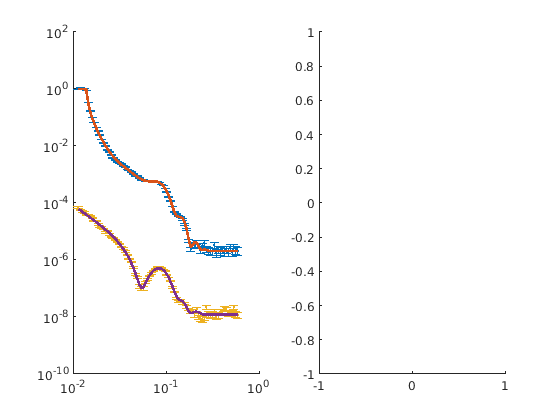


figure; 
plotRefSLD(out1,results)

Now repeat this but change it to a subtracted background.....

problem.backgroundConstr{1} = [0 1e-5];
problem.backgroundConstr{2} = [0 1e-5];
problem.contrastBacks{1}(2) = 2;
problem.contrastBacks{2}(2) = 2;
[out2,results2] = RAT(problem,controls)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          7.02016         
     1           30          6.85815         initial simplex
     2           32          6.83262         reflect
     3           34           6.5406         expand
     4           35           6.5406         reflect
     5           36           6.5406         reflect
     6           38           6.5406         contract inside
     7           39           6.5406         reflect
     8           40           6.5406         reflect
     9           41           6.5406         reflect
    10           42           6.5406         reflect
    11           43           6.5406         reflect
    12           44           6.5406         reflect
    13           45           6.5406         reflect
    14           46           6.5406         reflect
    15           47           6.5406         reflect
    16           48           6.5406         reflect
    17           49           6.54

out2 =   problemDef with properties:

         experimentType: 'standard'
     experimentGeometry: 'substrate/liquid'
                nParams: 22
                 params: [5.0407 18.7856 3.4002e-06 20.9848 -3.4812e-07 5.6850 8.0728 19.8914 4.9878e-10 9.8094 1.0050e-06 6.6985 27.7792 9.9998 1.0000e-06 4.1161 17.0979 -1.6181e-07 16.4901 29.5266 99.9963 23.6486]
             paramNames: {1×22 cell}
            paramConstr: {1×22 cell}
          paramFitYesNo: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
           nBackgrounds: 2
            backgrounds: [2.0169e-06 3.1881e-06]
        backgroundNames: {'Background D2O'  'Background 2'}
       backgroundConstr: {[0 1.0000e-05]  [0 1.0000e-05]}
     backgroundFitYesNo: [1 1]
          nScalefactors: 2
           scalefactors: [0.1031 0.1435]
       scalefactorNames: {'Scalefactor 1'  'Scalefactor 2'}
      scalefactorConstr: {[0.0500 0.2000]  [0.0500 0.2000]}
    scalefact

results2 = struct with fields:
          reflectivity: {2×1 cell}
            Simulation: {2×1 cell}
          shifted_data: {2×1 cell}
             layerSlds: {2×1 cell}
           sldProfiles: {2×1 cell}
             allLayers: {2×1 cell}
    calculationResults: [1×1 struct]
        contrastParams: [1×1 struct]


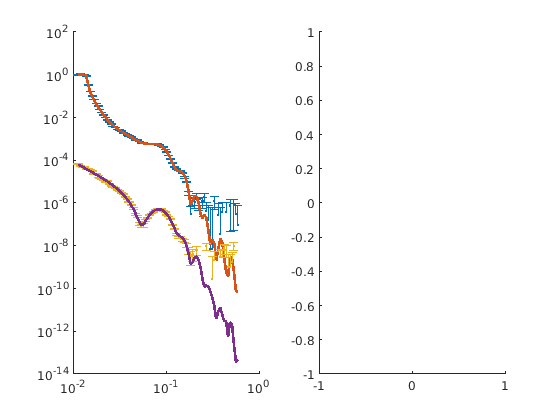

figure;
plotRefSLD(out2,results2)